# Setup

## Set Parameters for Chronux 

% Setting parameters
params.Fs = 1000; %Sampling frequency of input data (1000 = 1000 hz = 1 sample per millisecond)
params.fpass = [0 100]; % Which frequencies to look at [lowest_wanted highest_wanted]
params.pad = 0; % will add 0's to fit into a power of 2 for better calculation (0 is default and adds 0's to the next power of 2)
TW = 5; % the time-bandwidth product 
K = 9; % the number of tapers, K = 2*TW - 1 
params.tapers = [TW K]; 
params.err = [2 0.05]

params = struct with fields:
        Fs: 1000
     fpass: [0 100]
       pad: 0
    tapers: [5 9]
       err: [2 0.0500]


## Set General Parameters

Gparams.window = 20

Gparams = struct with fields:
                   window: 20
                movingwin: [20 1]
                    alpha: 0.9965
         standardized_len: 0
    artifact_filter_limit: 0.5000


Gparams.movingwin = [20 1]

Gparams = struct with fields:
                   window: 20
                movingwin: [20 1]
                    alpha: 0.9965
         standardized_len: 0
    artifact_filter_limit: 0.5000


Gparams.alpha = 0.9965

Gparams = struct with fields:
                   window: 20
                movingwin: [20 1]
                    alpha: 0.9965
         standardized_len: 0
    artifact_filter_limit: 0.5000


Gparams.standardized_len= 0

Gparams = struct with fields:
                   window: 20
                movingwin: [20 1]
                    alpha: 0.9965
         standardized_len: 0
    artifact_filter_limit: 0.5000


Gparams.artifact_filter_limit = 0.5

Gparams = struct with fields:
                   window: 20
                movingwin: [20 1]
                    alpha: 0.9965
         standardized_len: 0
    artifact_filter_limit: 0.5000



% Set Bounds for Band Extraction to look at particular band power with function band_extract()
Gparams.extract_lower_bound = 7

Gparams = struct with fields:
                   window: 20
                movingwin: [20 1]
                    alpha: 0.9965
         standardized_len: 0
    artifact_filter_limit: 0.5000
      extract_lower_bound: 7


Gparams.extract_upper_bound = 9

Gparams = struct with fields:
                   window: 20
                movingwin: [20 1]
                    alpha: 0.9965
         standardized_len: 0
    artifact_filter_limit: 0.5000
      extract_lower_bound: 7
      extract_upper_bound: 9


##  Load Each Dataset

I have removed CT7 and KO7 here as the trials were noisy

I have removed CT4 and KO4 as there is strong 52 Hz Noise

I have removed CT6 and KO6 as there is strong noise around 60 Hz

% Load each unhabituated trial for each
controls = {CT1, CT2, CT3, CT5, CT8}

controls = 1×5 cell array
    {1893260×2 single}    {3726858×2 single}    {3716176×2 single}    {3640352×2 single}    {3653016×2 single}


knockouts = {KO1, KO2, KO3, KO5, KO8}

knockouts = 1×5 cell array
    {1890190×2 single}    {3689071×2 single}    {3517539×2 single}    {3691845×2 single}    {3861380×2 single}



Ccat = vertcat_cell_array(controls)

Ccat = 16629662×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0591
    0.0165   -0.0742
    0.0149   -0.0644
    0.0156   -0.0772
    0.0123    0.0008
    0.0146   -0.0048
    0.0152   -0.0098
    0.0136   -0.0223
    0.0156   -0.0390


Kcat = vertcat_cell_array(knockouts)

Kcat = 16650025×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0759
    0.0024   -0.0456
    0.0054   -0.0561
    0.0034   -0.0413
    0.0037    0.0103
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0677
    0.0027   -0.0693



all_trials = [controls knockouts]

all_trials = 1×10 cell array
    {1893260×2 single}    {3726858×2 single}    {3716176×2 single}    {3640352×2 single}    {3653016×2 single}    {1890190×2 single}    {3689071×2 single}    {3517539×2 single}    {3691845×2 single}    {3861380×2 single}


# Running Data

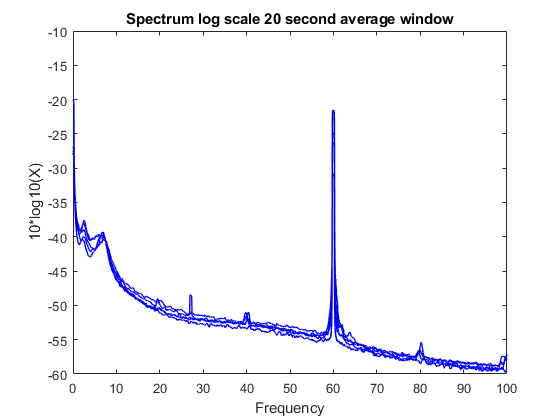

ans = 1×5 cell array
    {1×2 cell}    {1×2 cell}    {1×2 cell}    {1×2 cell}    {1×2 cell}


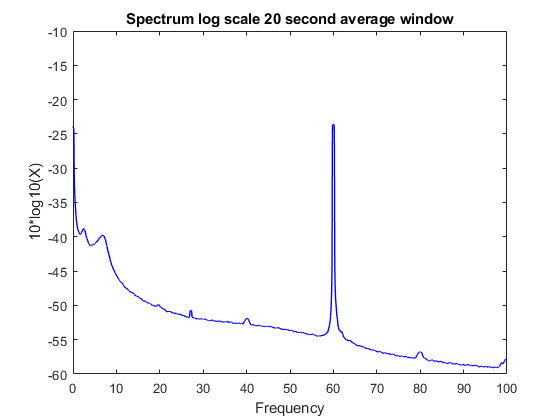

Percent Time Running = 17.9% 


z =    231   232   233   234   235   236   237   238   239   240   241   242   243   244   245   246   247   248   249   250   251   252   253   254   255   256   257   258   259   260   261   262   263   264   265   266   267   268   269   270   271   272   273   274   275   276   277   278   279   280


extracted = 	1.0e+-3 *

    0.1942    0.1901    0.1803    0.1617    0.1081    0.0767    0.0822    0.0839    0.0956    0.0874    0.0929    0.0881    0.0914    0.0899    0.0836    0.0912    0.0974    0.0930    0.0943    0.0925    0.1005    0.0956    0.0947    0.0814    0.0784    0.0785    0.0791    0.0783    0.0665    0.0612    0.0601    0.0471    0.0336    0.0329    0.0271    0.0260    0.0279    0.0254    0.0256    0.0312    0.0309    0.0438    0.0415    0.0375    0.0414    0.0354    0.0490    0.0441    0.0561    0.0443
    0.2013    0.2002    0.1765    0.1800    0.0992    0.0819    0.0747    0.0901    0.0985    0.0985    0.0973    0.0922    0.1076    0.1043    0.0921    0.1019    0.1037    0.0916    0.1032    0.0974    0.0987    0.0946    0.0901    0.0784    0.0776    0.0771    0.0786    0.0805    0.0708    0.0618    0.0616    0.0446    0.0313    0.0342    0.0297    0.0255    0.0274    0.0259    0.0234    0.0263    0.0341    0.0465    0.0412    0.0378    0.0401    0.0381    0.0511    0

extracted_mean = 	1.0e+-3 *

    0.0674
    0.0677
    0.0665
    0.0720
    0.0745
    0.0734
    0.0737
    0.0790
    0.0837
    0.0844


result = 	1.0e+-3 *

    0.0674
    0.0677
    0.0665
    0.0720
    0.0745
    0.0734
    0.0737
    0.0790
    0.0837
    0.0844


running_times =      0     0     0     0     0     1     1     1     0     0     0     1     1     1     1     0     1     1     1     1     1     1     1     1     0     0     0     1     1     1     1     1     1     1     1     0     1     0     1     0     1     1     1     0     0     0     0     1     1     1


running_power_mean = 9.4311e-05

resting_power_mean = 6.2480e-05

result = 1×2 cell array
    {[9.4311e-05]}    {[6.2480e-05]}


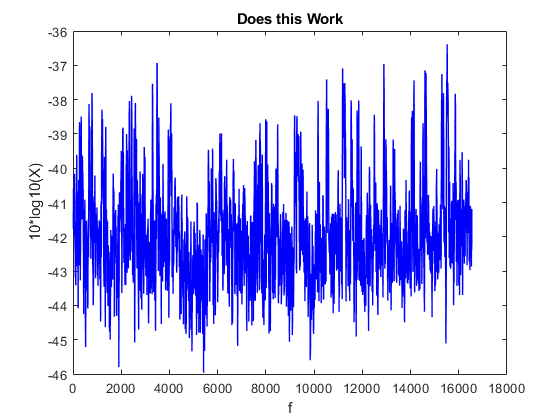

tic
LFP_analysis(controls, params, Gparams, 'Control', 1, 1, 0, 1, 1)

toc

Elapsed time is 145.496891 seconds.



disp('____________________________________________________________________________________________________________________________________________________________')

____________________________________________________________________________________________________________________________________________________________


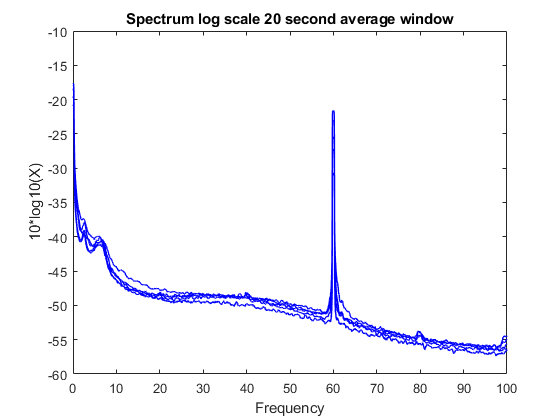

ans = 1×5 cell array
    {1×2 cell}    {1×2 cell}    {1×2 cell}    {1×2 cell}    {1×2 cell}


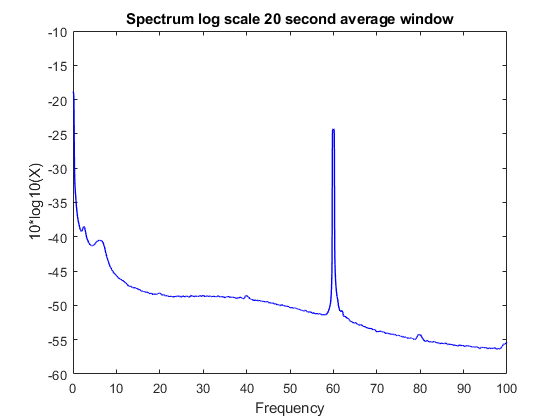

Percent Time Running = 37.3% 


z =    231   232   233   234   235   236   237   238   239   240   241   242   243   244   245   246   247   248   249   250   251   252   253   254   255   256   257   258   259   260   261   262   263   264   265   266   267   268   269   270   271   272   273   274   275   276   277   278   279   280


extracted = 	1.0e+-3 *

    0.1329    0.1329    0.1445    0.1459    0.1455    0.1543    0.1447    0.1382    0.1383    0.1272    0.1139    0.1088    0.1110    0.1130    0.1136    0.0867    0.0863    0.0789    0.0737    0.0665    0.0642    0.0686    0.0519    0.0567    0.0550    0.0709    0.0669    0.0692    0.0562    0.0589    0.0667    0.0675    0.0583    0.0409    0.0604    0.0572    0.0565    0.0592    0.0594    0.0645    0.0553    0.0524    0.0593    0.0579    0.0568    0.0486    0.0484    0.0591    0.0704    0.0694
    0.1139    0.1171    0.1233    0.1481    0.1313    0.1352    0.1249    0.1318    0.1301    0.1142    0.1123    0.0990    0.1076    0.1121    0.1017    0.0880    0.0629    0.0615    0.0632    0.0537    0.0601    0.0482    0.0463    0.0494    0.0378    0.0629    0.0605    0.0661    0.0469    0.0489    0.0598    0.0602    0.0496    0.0363    0.0448    0.0505    0.0461    0.0595    0.0623    0.0645    0.0560    0.0529    0.0560    0.0571    0.0558    0.0505    0.0477    0

extracted_mean = 	1.0e+-3 *

    0.0751
    0.0687
    0.0644
    0.0606
    0.0544
    0.0503
    0.0480
    0.0442
    0.0442
    0.0437


result = 	1.0e+-3 *

    0.0751
    0.0687
    0.0644
    0.0606
    0.0544
    0.0503
    0.0480
    0.0442
    0.0442
    0.0437


running_times =      0     0     0     0     0     0     0     1     1     1     1     1     1     0     0     0     0     1     1     1     1     1     0     1     1     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     1


running_power_mean = 4.6714e-05

resting_power_mean = 5.2038e-05

result = 1×2 cell array
    {[4.6714e-05]}    {[5.2038e-05]}


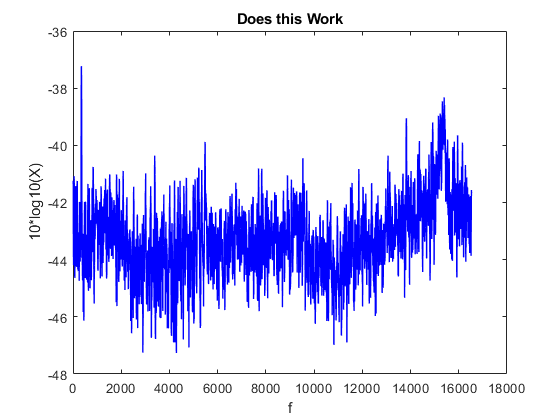


tic
LFP_analysis(knockouts, params, Gparams, 'Knockout', 1, 1, 0, 1, 1)

toc

Elapsed time is 149.456007 seconds.




LFP_analysis({Ccat Kcat}, params, Gparams, 'Together', 1, 1, 1, 1, 0, 1)

Undefined function 'abs' for input arguments of type 'cell'.

Error in LFP_Master_Draft_May8>artifact_filter (line 186)
array(abs(array(:,2)) >= limit, :) = [];

Error in LFP_Master_Draft_May8>LFP_analysis (

# **Functions**

# Analysis

## LFP Total Analysis  

function result = LFP_analysis(cell_array, params, Gparams, label, filter_data_01, analyze_running_01, analyze_individual_01, analyze_together_01, analyze_average_01, error_bars_01) 

% Set Default Values
if ~exist('label', 'var'), label = '';end
if ~exist('filter_data_01', 'var'), filter_data_01 = 0; end
if ~exist('analyze_running_01', 'var'), analyze_running_01 = 0; end
if ~exist('analyze_individual_01', 'var'), analyze_individual_01 = 0; end
if ~exist('analyze_together_01', 'var'), analyze_together_01 = 0; end
if ~exist('analyze_average_01', 'var'), analyze_average_01 = 1; end
if ~exist('error_bars_01', 'var'), error_bars_01 = 0; end

%Filter Artifacts from Data
if filter_data_01 == 1
    for jj = 1:length(cell_array)
        cell_array{jj} = artifact_filter(cell_array{jj}, Gparams.artifact_filter_limit);
    end
end

% Individual Trial Analysis
if analyze_individual_01 == 1
    for ii = 1:length(cell_array)
        
        % Plot Filtered Data
        title_filtered = sprintf('%s %f Filtered Data', label, ii);
       
        figure; plot(cell_array{ii}); title(title_filtered); 
        plot_spectrum(cell_array{ii}, params, Gparams.window, error_bars_01); title(title_filtered);
        
        
        if analyze_running_01 == 1
            running_data = process_running_data(cell_array{ii});
            percent_running(running_data);
            running_theta(cell_array{ii}, params, Gparams, running_data),title(title_filtered);
           
        elseif analyze_running_01 == 0
            plot_spectrogram(cell_array{ii}, params, Gparams.movingwin); title(title_filtered);
        end
        
        
    end    
end

% Analyze Together - Plot All Spectrums on One Figure
if analyze_together_01 == 1
    plot_spectrum(cell_array, params, Gparams.window, error_bars_01)
end


% Averaged Trial Analysis
if analyze_average_01 == 1
    
    %Averaged Analysis and plotting
    cat = vertcat_cell_array(cell_array);
    
    plot_spectrum(cat, params, Gparams.window);
    
    if analyze_running_01 == 1
        running_data = process_running_data(cat);
        percent_running(running_data);
        running_theta(cat, params, Gparams, running_data); title('Does this Work');
        
    elseif analyze_running_01 == 0
        plot_spectrogram(cat, params, Gparams.movingwin);
    end
    
end


end

## _____________________________________________________________________________

# Plotting Data

## Calculate and Plot Spectrum Segs 

    - Optional: Show Error Bars, Plot Together/Individually

function result = plot_spectrum(data, params, window, error_bars_01, individual_plot_01, segave_01)

% Set default argument values
if ~exist('window', 'var'), window = 20; end % window is length in seconds to average over
if ~exist('error_bars_01', 'var'), error_bars_01 = 0 ; end 
if ~exist ('individual_plot_01', 'var'), individual_plot_01 = 0; end
if ~exist('segave_01', 'var'), segave_01 = 1; end % Segave = 1 means it will average over the provided window

% If passing one array this converts it into a cell array for the function to handle
if ~iscell(data)
    data = {data};
end

x = [];

% Plot and return values given varous conditions (no error bars / error bars; indivudual/ grouped)
if error_bars_01 == 1
    
    if individual_plot_01 == 0
        figure;
        for ii = 1:length (data)
            
            [s,f, ~, ~, Serr]=mtspectrumsegc(data{ii}(:,2),window,params,segave_01);
            plot_vector(s,f, 'l', Serr); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
            hold on 
            
            x{ii} = {s, f, Serr} ;
        end
        
    elseif individual_plot_01 == 1
        for ii = 1:length (data)
            [s,f, ~, ~, Serr]=mtspectrumsegc(data{ii}(:,2),window,params,segave_01);
            figure; plot_vector(s,f, 'l', Serr); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
                         
            x{ii} = {s, f, Serr} ;
        end
    end
    
elseif error_bars_01 == 0
    if individual_plot_01 == 0
        figure;
        for ii = 1:length (data)
            [s, f] = mtspectrumsegc(data{ii}(:,2),window,params,segave_01);
            
            plot_vector(s, f, 'l'); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
            hold on 
            
            x{ii} = {s, f} ;
        end
    elseif individual_plot_01 == 1
        for ii = 1:length (data)
            [s,f]=mtspectrumsegc(data{ii}(:,2),window,params,segave_01);
            
            figure; plot_vector(s,f, 'l'); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
                         
            x{ii} = {s, f} ;
        end
    end
end
    
result = x;

end

## Calculate and Plot Spectrogram

function result = plot_spectrogram (arrayx, params, movingwin)

[s, t, f, Serr] = mtspecgramc(arrayx(:,2), movingwin,params);
figure; plot_matrix(s,t,f, 'l'); colorbar; colormap jet; caxis ([-70 -20]); xlabel('Seconds'); ylabel('Frequency (Hz)');
result = {s, t, f, Serr};
end

## ____________________________________________________

# Filtering and Shaping Data

## Vertically Concatenate Cell Array

function result = vertcat_cell_array(cell_array)
x = cell_array{1};
for ii = 2: length(cell_array)
    x = vertcat(x,cell_array{ii}); 
end
result = x;
end

## Filter out Artifacts (Array)

function result = artifact_filter(array, limit)

array(abs(array(:,2)) >= limit, :) = [];

result = array;
end

## Standardize Length of Arrays

function result = standardize_length(cell_array, len)
% This function takes a cell array (cell_array) containing a set of arrays
% and makes them all the same length (len) from 1 to len
for ii = 1:length(cell_array)
    cell_array{ii} = cell_array{ii}(1:len,:);
end
result = cell_array;
end


## Remove Frequency Band Noise from Cell Array of Datasets

function result = filter_noise(xarray, noiseHz, Fs, alpha)
% This function removes noise from signal with variable alpha and Hz

% Set parameters for filter

omega = 2*pi*noiseHz/Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

xarray (:,2) = filter(num,den,xarray(:,2));

result = xarray;
end

## Remove 60Hz Noise from Cell Array of Datasets

function result = remove60(cell_array, Fs)
% This function removes 60 Hz noise from signal

% Set parameters for filter

%%%%global params.Fs

alpha = 0.998; 
omega = 2*pi*60/Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

for ii = 1:length(cell_array)
    cell_array{ii}(:,2) = (filter(num,den,cell_array{ii}(:,2)));
end
result = cell_array;
end

## Remove 60Hz Noise from Array

function result = remove60_nocell(xarray, Fs, alpha)
% This function removes 60 Hz noise from signal

% Set parameters for filter

% alpha = 0.9975; 
omega = 2*pi*60/Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

xarray (:,2) = filter(num,den,xarray(:,2));

result = xarray;
end  


## ____________________________________________________________________________

# Movement Data Analysis

## Process Running Data into Boolean per Second

function result = process_running_data(LFP_data)

opto = round(LFP_data(:,1));
times = 1:length(opto);

win = 1000; %window in ms to look at opto
winstart = [1:win:length(times)-win]; %index corresponding to the start of each window

locomotion = []; %vector of 0 (not moving) and 1 (moving) for each window (1 sec)
for i = 1:length(winstart)
   m = winstart(i);
   optowin = opto(m:m+(win-1));
   optowinDif = diff(optowin); %will be all 0 if every value in optowin is the same
   if isempty(find(optowinDif,1)) %if optowinDif are all 0's
       locomotion(i) = 0; %0 means not moving
   else
       locomotion(i) = 1; %1 = moving
   end
end
result = locomotion;
end

## Percent Running Time

function result = percent_running(running_data)
result = sum(running_data(:) == 1)/length(running_data);
fprintf ('Percent Time Running = %.01f%% \n', result*100);
end

## Total Time Running (Seconds)

function result = time_running(running_data)
result = sum(running_data(:) == 1);
fprinf ('Total Time Running is %s \n', result)
end

## Extract Band

function result = band_extract(pp_data, lower_bound, upper_bound)
z = find(pp_data{3} > lower_bound & pp_data{3} < upper_bound)

extracted = pp_data{1}(:, z)

extracted_mean = mean (extracted, 2)

plot_vector(extracted_mean, pp_data{2})


result = extracted_mean
end

## Compare Extracted Power to Running State

function result  = running_theta (data, params, Gparams, running_times)

if ~exist('running_data', 'var'), running_times = process_running_data(data); end

spec = plot_spectrogram(data, params, Gparams.movingwin);
mean_power_per_time = band_extract (spec, Gparams.extract_lower_bound, Gparams.extract_upper_bound);




% Remove first and last seconds from running times to match spec data, remove window/2 from each side
running_times = running_times(Gparams.movingwin(1)/2:length(running_times)-Gparams.movingwin(1)/2)

running_power_mean = mean(mean_power_per_time(running_times == 1))
resting_power_mean = mean(mean_power_per_time(running_times == 0))

result = {running_power_mean, resting_power_mean}
end
